** Classifying Breast Cancer :**

The data-set is to be  downloaded from the **UC Irvine Machine Learning Repository. **The classifier is designed and evaluated using a systematic approach to data analytics. The data-set used here is** Breast Cancer Data Set.**

clear;
file_destination='breast-cancer-wisconsin.csv'; 

The downloaded file breast-cancer-wisconsin*.csv *is   a comma seperated text file.

T = readtable(file_destination, 'FileType','text', 'Delimiter', 'comma',"VariableNamingRule","preserve");

% removes missing rows.
rmmissing(T);

Let us validate  the data using an appropriate visualisation technique. 

cancer_data=ans(:, 1:13);
inpCancer_data=table2array(cancer_data(:,2:9));      %Input data matrix.
outCancer_data=table2array(cancer_data(:,12:13));     %Target data matrix.

x = inpCancer_data';
t = outCancer_data';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainbr';  % Scaled conjugate gradient backpropagation.


% Create a Pattern Recognition Network
hiddenLayerSize = 14;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

net.trainParam.epochs      = 5000;

% Train the Network
[net,tr] = train(net,x,t);


% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0045

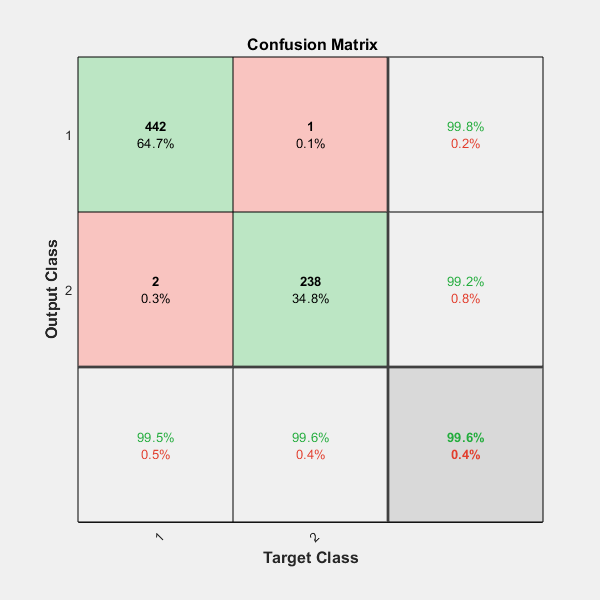

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
view(net)

% Plots
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(t,y)